**Cystinosis Disease Detector**

Loading the data:

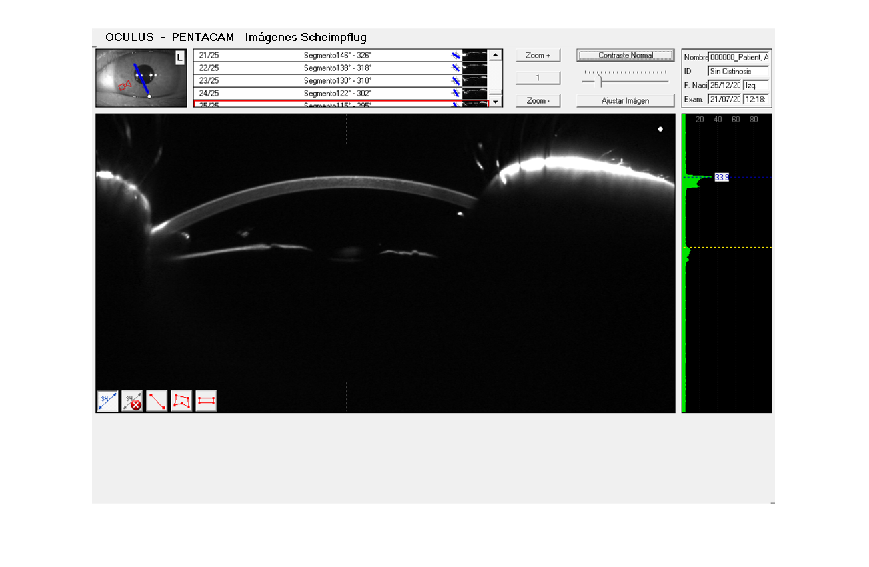

cd( '../data' )
patients = dir;
aux = cell( 1, numel( patients )-2 );
for i=3:numel( patients)
    aux{i-2} = patients(i).name;
end
patients = aux;

I = cell( 1, numel( patients ) );
for i = 1:numel( patients )
    D = patients{i}; %directory where the files are saved
    S = dir( fullfile(D,'*.BMP') ); % pattern to match filenames.
    I{i} = cell( 1, numel(S) );
    for k = 1:numel(S)
        F = fullfile( D, S(k).name );
        I{i}{k} = imread( F );
        imshow( I{i}{k} );
    end
end

Pre-processat: per millorar la qualitat de la imatge de manera que és millori el processat posterior (ex: eliminació de soroll, millora contrast, etc).

Obtenció de les característiques necessàries per tal caracteritzar els elements a segmentar.

Localització dels objectes: segmentar la imatge original per diferenciar els objectes d’interès.

Amb la informació extreta de la imatge realitzar la tasca demanada.